# Generating amplitude and phase modulated signals using state-variable methods

This work is based upon the work of Jerry Stanbakken at the National Institute of Standards and Technology and published in:

[Calculating Combined Amplitude and Phase Modulated Power Signals](https://ieeexplore.ieee.org/document/6039442/)

A combined amplitude and phase modulated sinewave is given by:


$$X_a = X_m[1+k_x\cos(\omega_x t+\phi_x)]cos(\omega_0t+k_a\sin(\omega_at+\phi_a)+\theta)$$


(subscript x denotes magnitude and subscript a denotes angle)

Xm = 1;         % Fundamental magnitude
w0 = 50*2*pi;   % Fundamental frequncy
theta = 0/(180/pi);
kx = .1;       % Amplitude modulation (AM) index (a percent of fundamental magnitude)
wx = 1*2*pi;         % AM frequency
phi_x = 0/(180/pi);      % AM initial phase
ka = 0; % Phase modulation (PM) index (radians)
wa = 1*2*pi;         % PM frequency
phi_a = 0;      % PM initial phase

Fs = 4096;         % sample rate
duration = 4;  % signal duration (seconds)
t = 0:1/Fs:duration;

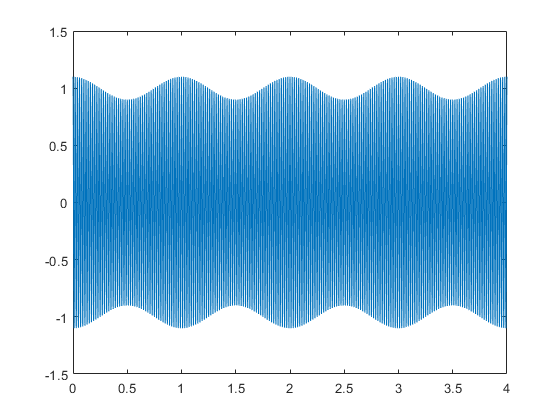

%Xa = (Xm + (kx*cos(wx*t+phi_x))).*cos(w0*t+(ka*sin(wa*t+phi_a)));
Xa = AmPm(Xm,kx,wx,phi_x,w0,theta,ka,wa,phi_a,t);
plot (t,Xa);

## Analysis of the modulated waveform

Fourier analysis of a window of waveform samples such that an integer number of cycles of both the fundamental and the modulation will show that in the frequency domain, the modulated signal is made up of the fundamental and a number of side bands.  It is important to analyse both an integer number of fundamental and modulation cycles to avoid [spectral leakage](https://en.wikipedia.org/wiki/Spectral_leakage).

For AM modulation only, the signal is made up of the fundamental and two side-bands:

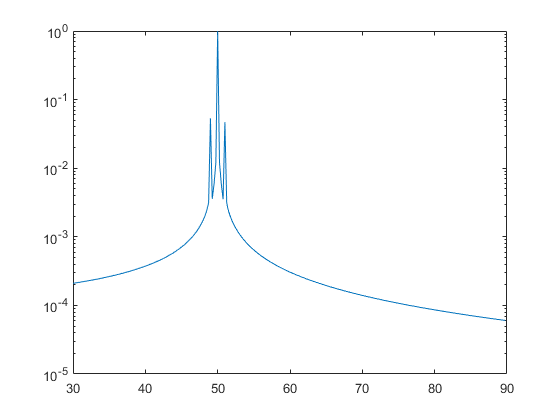

ka = 0;     % set the PM index to 0
Xa = AmPm(Xm,kx,wx,phi_x,w0,theta,ka,wa,phi_a,t);
Y = fft(Xa); % get the fft of the signal

L = duration*Fs;    % number of samples
P2 = abs(Y/L);  %two-sided amplitude spectrum
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);    %single-sided spectrum
f = Fs*(0:L/2)/L;
semilogy(f((30*duration)+1:90*duration),P1((30*duration)+1:90*duration))

For FM, there are many sidebands:

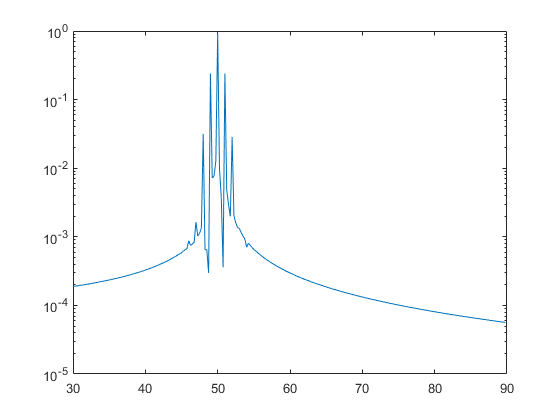

kx = 0;     % set the PM index to 0
ka = .5;
Xa = AmPm(Xm,kx,wx,phi_x,w0,theta,ka,wa,phi_a,t);
Y = fft(Xa); % get the fft of the signal

L = duration*Fs;    % number of samples
P2 = abs(Y/L);  %two-sided amplitude spectrum
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);    %single-sided spectrum
f = Fs*(0:L/2)/L;
semilogy(f((30*duration)+1:90*duration),P1((30*duration)+1:90*duration))

But 5 bands (the fundamental and two on each side) are the only significant (see Stenbakken for the uncertainty of not including more than 2 sidebands)

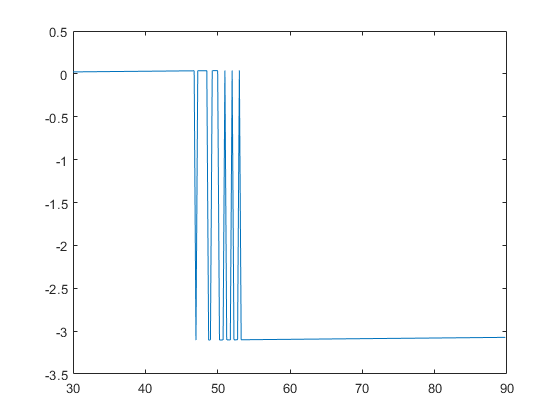

Arg = angle(Y);
Arg = Arg(1:L/2+1);
plot(f((30*duration)+1:90*duration),Arg((30*duration)+1:90*duration));

## Amplitude modulation equation and state-space representation

Expanding the general amplitude modulation equation:


$$X_a = X_m[1+k_x\cos(\omega_x t+\phi_x)]cos(\omega_0t+\theta)$$


we get the fundamental and two sidebands:


$$X_a = X_m\cos(\omega_0t+\theta)+X_m\frac{k_x}{2}\cos((\omega_0-\omega_x) t-\phi_x)]+X_m\frac{k_x}{2}\cos(\omega_0+\omega_x)t+\phi_x)$$


A state-space representation takes the form:


$$\dot x = Ax+ Bu\\
y = Cx+Du$$


State-space uses a 2x2 "A" matrix to model a single oscillating system. A naturally oscillating system takes the form:


$$\left\lbrack \begin{array}{cc}
0 & 1\\
-\omega^2  & 0
\end{array}\right\rbrack$$


 Creating a 6 x 6 matrix, with three 2x2 matrices on the diagonal will create 3 frequencies that can be summed together:

$\left\lbrack \begin{array}{ccc}
\left\lbrack \mathrm{sideband}\right\rbrack  & \; & \;\\
\; & \left\lbrack \mathrm{fundamental}\right\rbrack  & \;\\
\; & \; & \left\lbrack \textrm{sideband}\right\rbrack 
\end{array}\right\rbrack$ A

The phase shifts require a sum of both the $X_1$ and $X_2$ values of the $X$ matrix.  Since the $X_2$ values of derivatives of $cos(\omega t)$, The $X_2$ values must be scaled by $\frac{1}{\omega}$

The summing matrix C will take the form:


$$\left\lbrack \begin{array}{cccccc}
\frac{\textrm{kx}}{2}\cos {\;\phi }_x  & -\frac{\textrm{kx}}{2}\frac{\sin {\;\phi }_x }{\left(\omega_0 -\omega_a \right)} & X_m \;\cos \;\theta  & X_m \frac{\sin \;\theta }{\omega_0 } & \frac{\textrm{kx}}{2}\cos {\;\phi }_x  & \frac{\textrm{kx}}{2}\frac{\sin {\;\phi }_x }{\left(\omega_0 +\omega_a \right)}\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack C$$


**Note that this does not work when the fundamental phase **$\theta$** is not equal to 0.  Further investigation is needed.**

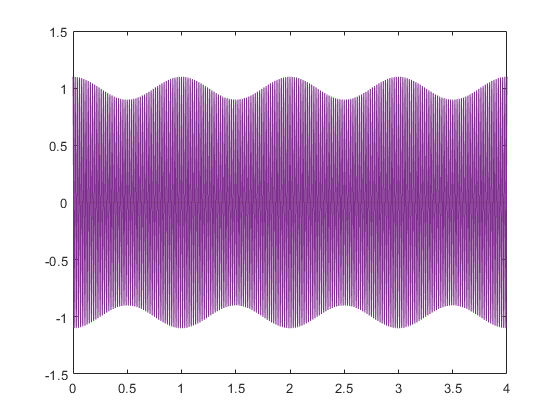

kx = 0.1;
ka = 0;

Side1 = [0,1;-(w0-wx)^2,0];
Fund = [0,1;-w0^2,0];      
Side2 = [0,1;-(w0+wx)^2,0];
Zeros = [0,0;0,0];


A = [Side1,Zeros,Zeros;...
     Zeros,Fund,Zeros;...
     Zeros,Zeros,Side2];
    
B=[1,0,0,0,0,0;...
   0,0,1,0,0,0;...
   0,0,0,0,1,0]';


C=[kx/2*cos(phi_x),-kx/2*(sin(phi_x)/(w0-wa)),Xm*cos(theta),Xm*sin(theta)/w0,kx/2*cos(phi_x),kx/2*(sin(phi_x)/(w0+wa));...
   0,0,0,0,0,0;...
   0,0,0,0,0,0];

D=0;
Sys=ss(A,B,C,D);
[y,t,x]=initial(Sys,[1,0,1,0,1,0]',[0:1/Fs:duration]);
Xa = AmPm(Xm,kx,wx,phi_x,w0,theta,ka,wa,phi_a,t);
plot (t,y);
hold on
plot (t,Xa);
hold off

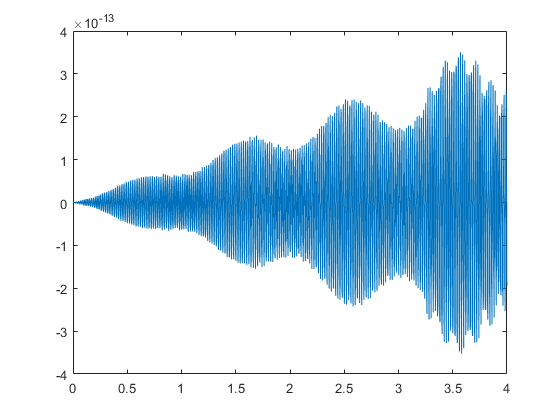


diff = y(:,1)-Xa;
plot (t,diff);

The error of the state-variable system increases over time.  this may be due to the way Matlab is accumulating time, if it is a floating point number, then time error accumulates over time.  For 4 seconds, the difference is negligible but for longer waveforms, it may become significant.

## Phase modulation

A phase modulated signal is given by:


$$X_a = X_m\cos(\omega_0t+k_a\sin(\omega_at+\phi_a))$$


As shown above, thie yeilds a family of sidebands with frequency spacing equal to the modulation frequency.  The signal is expanded and given by:


$$X_a  = X_m[J_0(k_a)cos(\omega0t)]\\
+ J_1(k_a)[[cos(\omega0+\omega_a)t + \phi_a]-[cos(\omega0-\omega_a)t - \phi_a]]\\
+J_2(k_a)[[cos(\omega0+2\omega_a)t +2 \phi_a]+[cos(\omega0-2\omega_a)t - 2\phi_a]]\\
+J_3(k_a)[cos(\omega0+3\omega_a)t +3 \phi_a]-[cos(\omega0-3\omega_a)t - 3\phi_a]]\\
+\ ...]
$$


where $J_n(k_a)$ is the nth order Bessel function of the first kind:


$$J_0(k_a)\cong1-\frac{k_a^2}{2^2},\;\;\;\;       J_1(k_a)\cong \frac{k_a}{1!2!}\\
J_2(k_a)\cong \frac{k_a^2}{2!2^2},\;\;\;\; J_3(k_a)\cong \frac{k_a^3}{3!2^3},\;\;\;\; etc!$$


Note how the higher order sidebands drop off very quickly.

Creating a 6 x 6 matrix, with three 2x2 matrices on the diagonal will create 3 frequencies that can be summed together:

$\left\lbrack \begin{array}{ccccc}
\left\lbrack \mathrm{sideband21}\right\rbrack  & \; & \; & \; & \;\\
\; & \left\lbrack \mathrm{sideband11}\right\rbrack  & \; & \; & \;\\
\; & \; & \left\lbrack \mathrm{fundamental}\right\rbrack \; & \; & \;\\
\; & \; & \; & \left\lbrack \mathrm{sideband12}\right\rbrack  & \;\\
\; & \; & \; & \; & \left\lbrack \mathrm{sideband22}\right\rbrack 
\end{array}\right\rbrack$A

The summing matrix C will take the form:


$$\left\lbrack \begin{array}{ccccccccc}
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
J_2 \left(k_a \right) & 0 & {-J}_1 \left(k_a \right) & 0 & {\mathrm{X}}_m J_0 \left(k_a \right) & 0 & J_1 \left(k_a \right) & 0 & J_2 \left(k_a \right)\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack C$$


kx = 0;
ka = 0.1;
wa = 1*2*pi;
phi_a = 0/(180/pi);
duration = 1;

Fund = [0,1;-w0^2,0];
Side11 = [0,1;-(w0-wa)^2,0];        
Side12 = [0,1;-(w0+wa)^2,0];
Side21 = [0,1;-(w0-2*wa)^2,0];
Side22 = [0,1;-(w0+2*wa)^2,0];
Side31 = [0,1;-(w0-3*wa)^2,0];
Side32 = [0,1;-(w0+3*wa)^2,0];
Zeros = [0,0;0,0];

A = [Side31,Zeros,Zeros,Zeros,Zeros,Zeros,Zeros;...
     Zeros,Side21,Zeros,Zeros,Zeros,Zeros,Zeros;...
     Zeros,Zeros,Side11,Zeros,Zeros,Zeros,Zeros;...
     Zeros,Zeros,Zeros,Fund,Zeros,Zeros,Zeros;...
     Zeros,Zeros,Zeros,Zeros,Side12,Zeros,Zeros;...
     Zeros,Zeros,Zeros,Zeros,Zeros,Side22,Zeros;
     Zeros,Zeros,Zeros,Zeros,Zeros,Zeros,Side32];
 
B=[1,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,1,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,1,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,1,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,1,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,1,0,0,0;
   0,0,0,0,0,0,0,0,0,0,0,0,1,0;]';

% Bessel functions
J0 = besselj(0,ka);
J1 = besselj(1,ka);
J2 = besselj(2,ka);
J3 = besselj(3,ka);

C=[0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   -J3*cos(phi_a),...
      J3*sin(phi_a)/(w0-3*wa),...
        J2*cos(phi_a),...
         -J2*sin(phi_a)/(w0-2*wa),...
          -J1*cos(phi_a),...
            J1*sin(phi_a)/(w0-wa),...
              Xm*J0,0,...
               J1*cos(phi_a),...
                J1*sin(phi_a)/(w0-wa),...
                 J2*cos(phi_a),...
                  J2*sin(phi_a)/(w0-2*wa),...
                   J3*cos(phi_a),...
                    J3*sin(phi_a)/(w0-3*wa);...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0];

D = 0;

Sys=ss(A,B,C,D);
[y,t,x]=initial(Sys,[1,0,1,0,1,0,1,0,1,0,1,0,1,0]',[0:1/Fs:duration]);


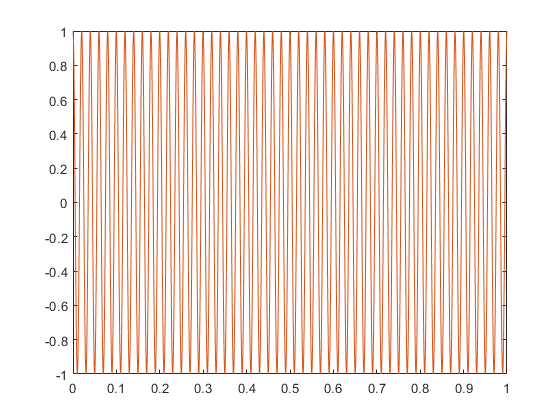

Xa = AmPm(Xm,kx,wx,phi_x,w0,theta,ka,wa,phi_a,t);
plot (t,y(:,4));
hold on
plot (t,Xa);
hold off

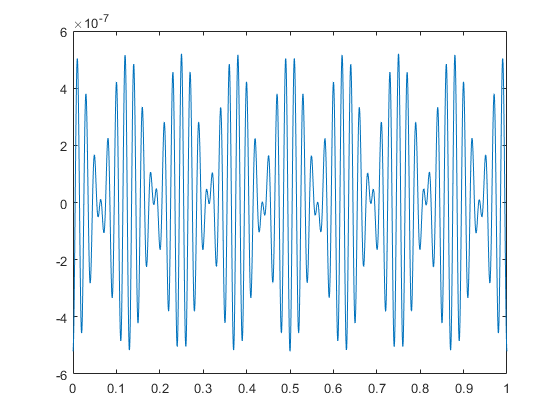

diff = y(:,4)-Xa;
plot (t,diff);

## Combined amplitude and phase modulation

If the modulation frequencies are different, then each sideband of the phase modulaton would require sidebands of the amplitude modulation (tripling the number of oscillators.

If the modulation frequencies are the same, and the starting phases $\phi_x\ and\ \phi_a$ were different, then this gets much, much more complicated!

**For now, this does not support amplitude and phase modulation phase offsets **$\phi_x$** and **$\phi_a$

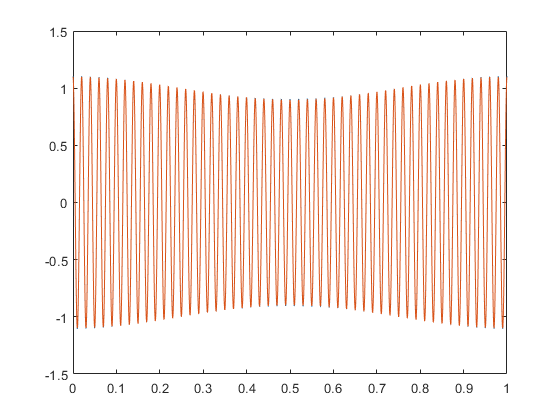

kx = 0.1;
ka = 0.1;

% Bessel functions
J0 = besselj(0,ka);
J1 = besselj(1,ka);
J2 = besselj(2,ka);
J3 = besselj(3,ka);
J4 = besselj(4,ka);

C=[0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   (-J3+(J2*kx/2+J4*kx/2)),0,(J2+(J1*kx/2)+(J3*kx/2)),0,(-J1+(J0*kx/2)+(J2*kx/2)),0,Xm*J0,0,(J1+(J0*kx/2)+(J2*kx/2)),0,(J2+(J1*kx/2)+(J3*kx/2)),0,(J3+(J2*kx/2+(J4*kx/2))),0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0;...
   0,0,0,0,0,0,0,0,0,0,0,0,0,0];

Sys=ss(A,B,C,D);
[y,t,x]=initial(Sys,[1,0,1,0,1,0,1,0,1,0,1,0,1,0]',[0:1/Fs:duration]);

Xa = AmPm(Xm,kx,wx,phi_x,w0,theta,ka,wa,phi_a,t);
plot (t,y(:,4));
hold on
plot (t,Xa);
hold off

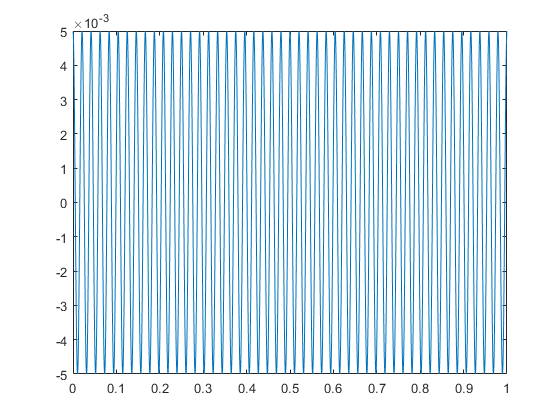

diff = y(:,4)-Xa;
plot (t,diff)

function [Xa] = AmPm(Xm,kx,wx,phi_x,w0,theta,ka,wa,phi_a,t)
    Xa = (Xm + (kx*cos(wx*t+phi_x))).*cos(w0*t+(ka*sin(wa*t+phi_a))+theta);
end 